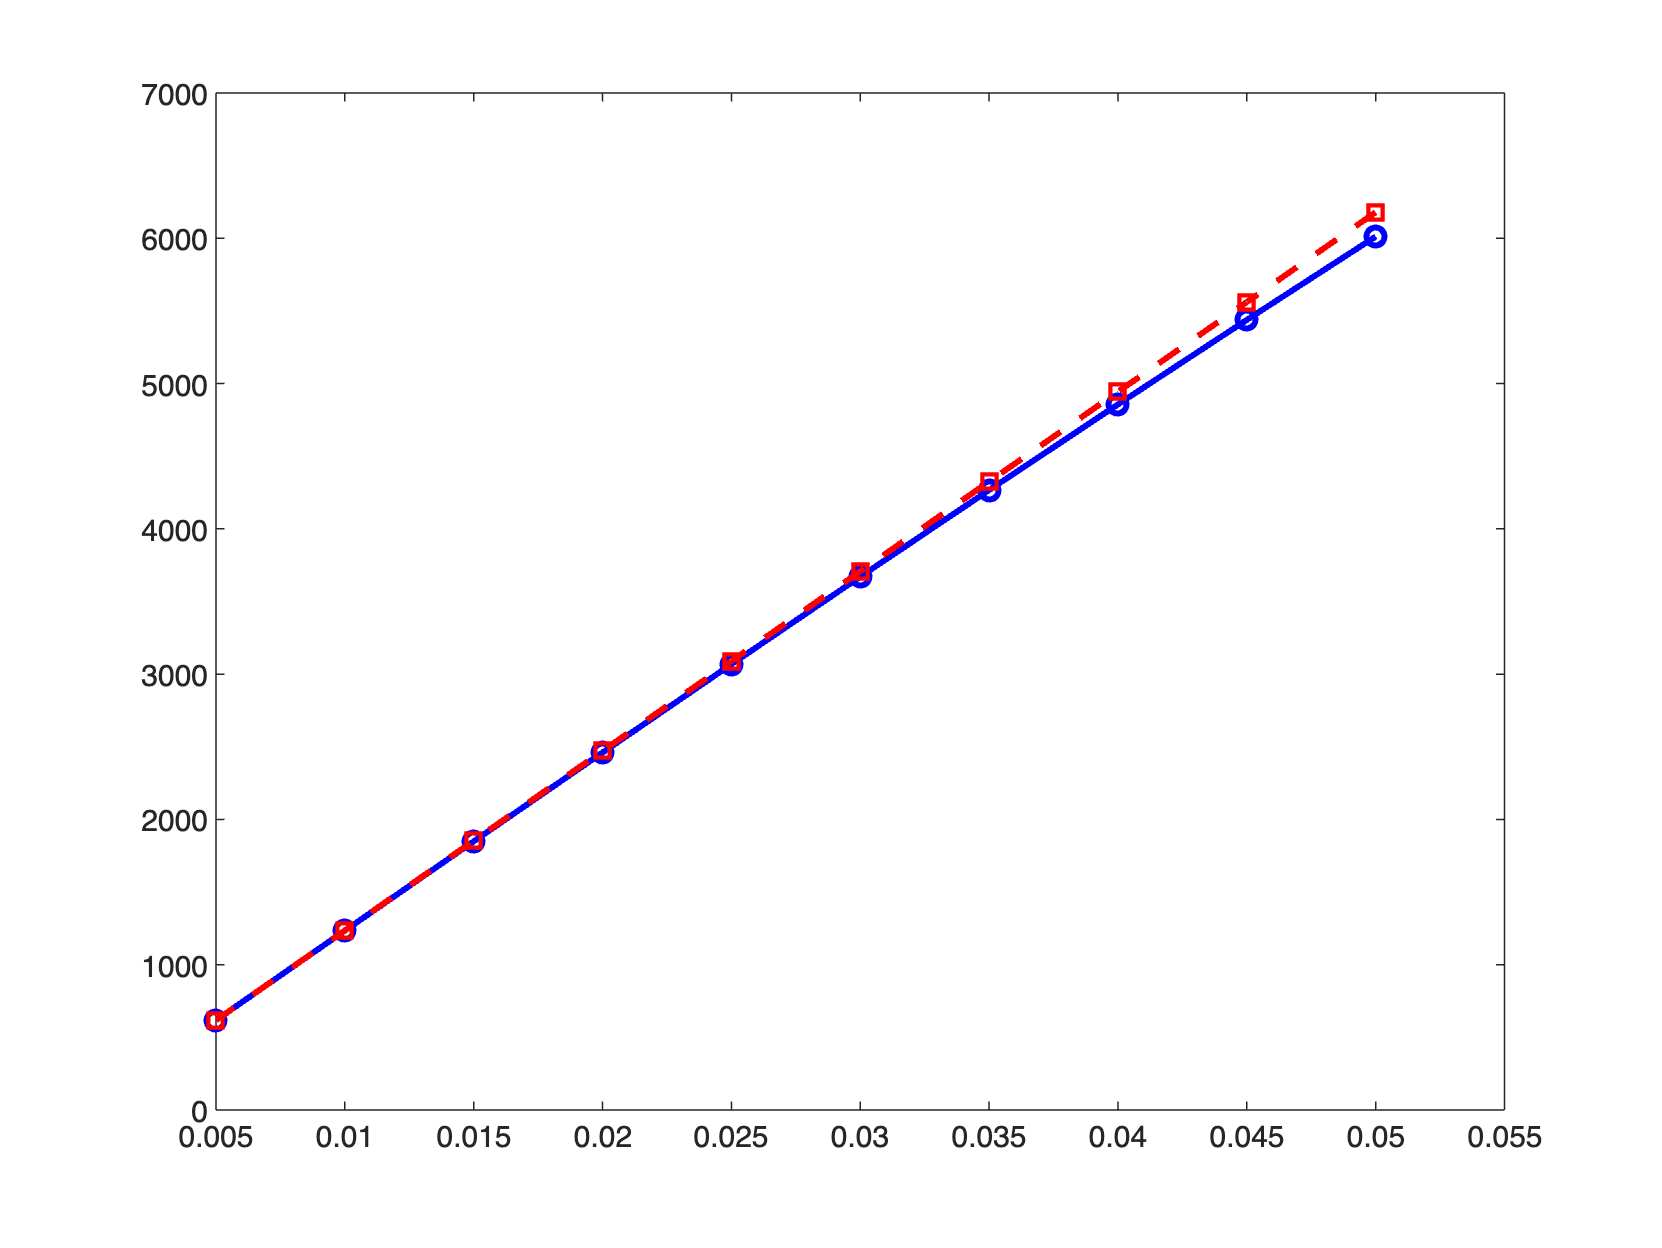

l = 0.5;
E = 210e9;
nu = 0.3;
rho = 7850;
k = 5/6;

h_max = 0.005;
h_min = 0.05;
h_values = linspace(h_min,h_max,10);

ratios = l ./ h_values;
exact_thick = zeros(1,length(h_values));
exact_thin = zeros(1,length(h_values));
error = zeros(1,length(h_values));

for i=1:length(h_values)
    hi=h_values(i);
    exact_thick(i) = computeExactFrequency(l, l, hi, nu, E, rho, k, 1,1);

    D = E * hi^3 / (12 * (1 - nu^2));
    exact_thin(i) = 2*pi^2/l^2*sqrt(D/(rho*hi));

    error(i)= exact_thick(i) - exact_thin(i);
end

figure;
plot(h_values, exact_thick, 'b-o', 'LineWidth', 2, 'MarkerSize', 6); 
hold on;
plot(h_values, exact_thin, 'r--s', 'LineWidth', 2, 'MarkerSize', 6);
hold off;